## Classify Query Data

Classify a new point based on the last two columns of the Fisher iris data. Using only the last two columns makes it easier to plot.

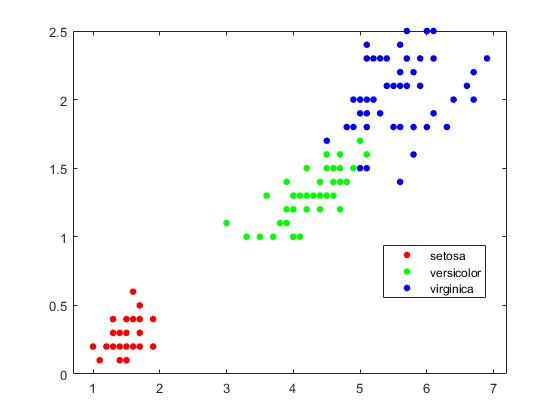

load fisheriris
x = meas(:,3:4);
gscatter(x(:,1),x(:,2),species)
legend('Location','best')

Plot the new point

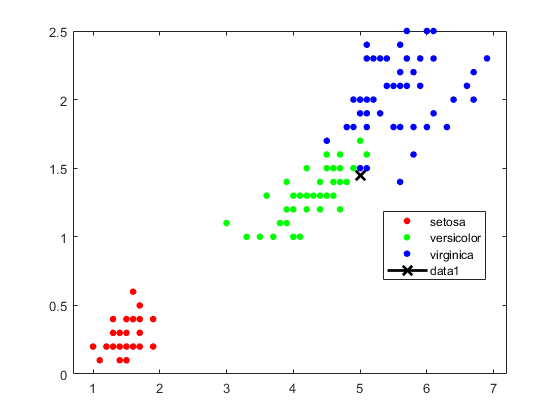

newpoint = [5 1.45];
line(newpoint(1),newpoint(2),'marker','x','color','k',...
   'markersize',10,'linewidth',2)

Prepare a *K*d-tree neighbor searcher model.

Mdl = KDTreeSearcher(x)

Mdl =   KDTreeSearcher - 属性:

       BucketSize: 50
         Distance: 'euclidean'
    DistParameter: []
                X: [150×2 double]


Find the 10 sample points closest to the new point.

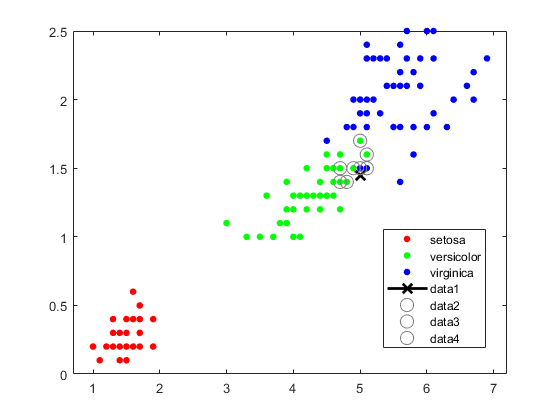

[n,d] = knnsearch(Mdl,newpoint,'k',10);
line(x(n,1),x(n,2),'color',[.5 .5 .5],'marker','o',...
    'linestyle','none','markersize',10)

In fact, this particular dataset contains duplicate values.

x(n,:)

ans =                          5                       1.5
                       4.9                       1.5
                       4.9                       1.5
                       5.1                       1.5
                       5.1                       1.6
                       4.8                       1.4
                         5                       1.7
                       4.7                       1.4
                       4.7                       1.4
                       4.7                       1.5


Find the species of the 10 neighbors.

tabulate(species(n))

       Value    Count   Percent
   virginica        2     20.00%
  versicolor        8     80.00%


## **Predict Classification Using KNN Classifier**

Construct a KNN classifier

load fisheriris
X = meas;    
Y = species; 
Mdl = fitcknn(X,Y,'NumNeighbors',4);

Predict the classification

flwr = mean(X); % an average flower
flwrClass = predict(Mdl,flwr)

flwrClass = 1×1 cell 数组
    {'versicolor'}
